# Ammonia storage results

This is the analysis of the results of the compressed air energy storage

load amonia_harald.mat

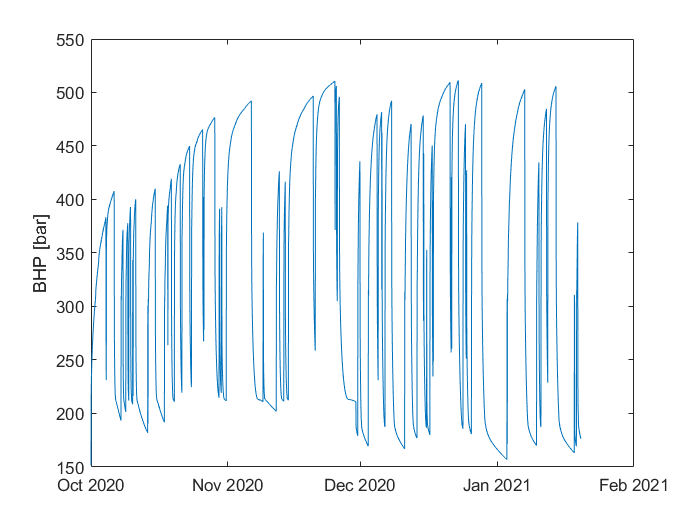

ans = 	1.0e+07 *

    1.7649    1.7649    1.7649    1.7649    1.7648    1.7649    1.7650    1.7651    1.7651    1.7651
    1.9824    1.9824    1.9824    1.9823    1.9823    1.9824    1.9825    1.9825    1.9825    1.9825
    2.0030    2.0020    2.0020    2.0039    2.0045    2.0034    2.0019    2.0014    2.0021    2.0026
    2.0328    2.0306    2.0307    2.0346    2.0359    2.0335    2.0301    2.0292    2.0305    2.0316
    2.0401    2.0382    2.0383    2.0412    2.0421    2.0401    2.0374    2.0366    2.0377    2.0387
    2.0288    2.0277    2.0276    2.0290    2.0293    2.0282    2.0266    2.0262    2.0268    2.0273
    2.0107    2.0101    2.0100    2.0105    2.0104    2.0097    2.0090    2.0087    2.0089    2.0091
    1.9914    1.9911    1.9910    1.9912    1.9911    1.9905    1.9898    1.9894    1.9894    1.9894
    1.9721    1.9719    1.9719    1.9724    1.9723    1.9715    1.9705    1.9700    1.9699    1.9699
    1.9522    1.9519    1.9520    1.9529    1.9529    1.9518    1.9506   

plot(d_long.HourDK(1:end-1), p_hist(1:end-1)/1e5)
ylabel('BHP [bar]')
saveas(gcf, 'ammonia_p_hist.jpg')

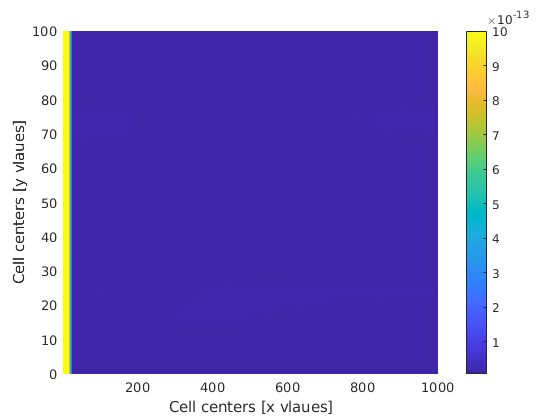

hFig = figure(1);
set(hFig, 'Position', [200 200 1500 500]);
visualizeCells(k); axis normal; shading interp;
saveas(gcf, 'ammonia_perm_harald.jpg')

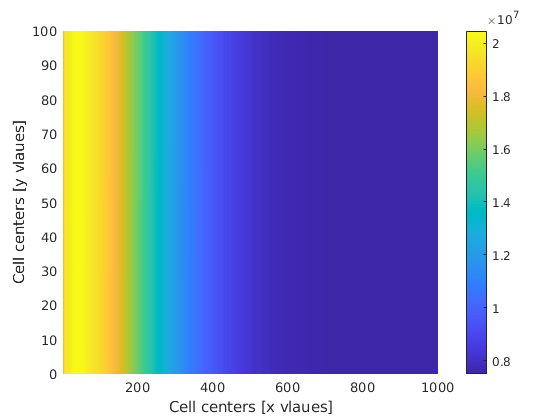

hFig = figure(2);
set(hFig, 'Position', [200 200 1500 500]);
visualizeCells(p_val); shading interp; axis normal;
saveas(gcf, 'ammonia_pressure_harald.jpg')

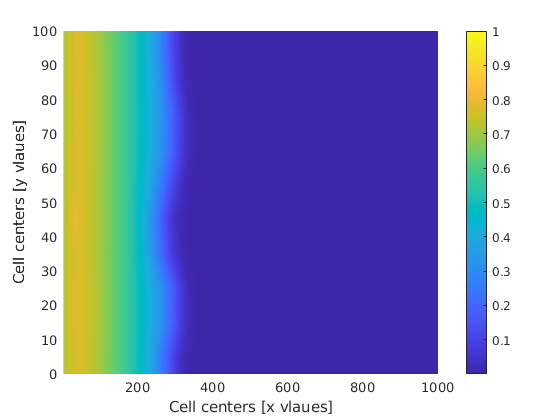

hFig = figure(3);
set(hFig, 'Position', [200 200 1500 500]);
visualizeCells(c_init); shading interp; axis normal;
saveas(gcf, 'ammonia_tracer_harald.jpg')

consumed_elec = sum((m_hist>0)*elec_max/1e6) % MWh

consumed_elec = 146800

% w_isentropic = compressor_station(p_atm, p_inj, comp_ratio, comp, T_inj);
% MW_ammonia = 0.017; % kg/mol
% chem_ex = 330000; % J/molproduced_elec = 0;
eta_elec_prod = 0.6;  % electricity from ammonia
for i=1:length(p_hist)
    if m_hist(i)<0
        produced_elec = produced_elec+m_hist(i)*(chem_ex/MW_ammonia)*eta_elec_prod;
    end
end
produced_elec = -produced_elec/1e6

produced_elec = 3.3966e+03


produced_elec/consumed_elec

ans = 0.0231